# Expand Example 2.12:

This live script is for use with the textbook

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

A second order system is described by the difference equation


$$y[n]-\frac{5}{6}\,y[n-1]+\frac{1}{6}\,y[n-2] = 0$$


Its natural response is in the form


$$y_{h}[n] =
c_{1}\,\left(\frac{1}{2}\right)^{n} +
c_{2}\,\left(\frac{1}{3}\right)^{n}$$
 

for $n\ge 0$.  Imposing the initial conditions for $n=-1$ and $n=-2$ yields

 
$$\begin{array}{r l}
y_{h}[-1] &=2\,c_{1}+3\,c_{2} \\
y_{h}[-2] &=4\,c_{1}+9\,c_{2}
\end{array}
$$


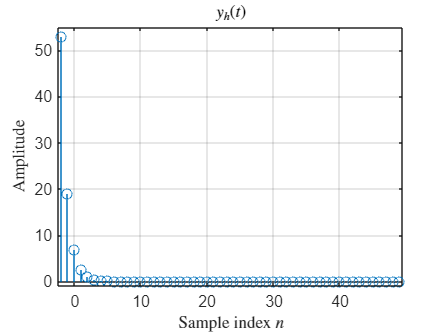

ym1 =19; % Enter y[-1]
ym2 =53; % Enter y[-2]
%
n = [-2:49];    % Vector of sample indices
% Compute the natural response
A = [2,3;4,9];
B = [ym1;ym2];
C = A\B;
yh = C(1)*(0.5).^n+C(2)*(1/3).^n;
% *Graph the natural response
stem(n,yh); grid;
axis([-2.5,49.5,-1,55]);
set(0,'defaultTextInterpreter','latex');
title('$y_h(t)$');
xlabel('Sample index $n$'); 
ylabel('Amplitude');

set(0,'defaultTextInterpreter','tex');